# Sistemi Dinamici - Prova parziale 22/12/2023

**voto massimo: x punti**

Il voto finale sarà costituito dalla somma delle valutazioni conseguite nei due esercizi.

## Esercizio 1

Sono state eseguite $3$ serie ripetute di esperimenti, acquisendo in ciascuna serie di esperimenti $20$ realizzazioni (tutte della stessa durata, quindi tutte col medesimo numero di campioni) della varaibile aleatoria $y(t)$ di un processo stocastico stazionario. 

Le acquisizioni sono state eseguite con frequenza di campionamento $f_S = 1.0 \;\text{kHz}$.

Le $3$ serie di esperimenti sono caratterizzate dall'avere numero di campioni differente ttra una serie e l'altra. In particolare

- serie $1$: sono state raccolte $20$ realizzazioni ciascuna con $2000$ campioni;

- serie $2$: sono state raccolte $20$ realizzazioni (sempre dallo stesso processo stocastico stazionario), ciascuna con $4000$ campioni;

- serie $3$: sono state raccolte $20$ realizzazioni, ciascuna contenente $6000$ campioni.

I dati sono a disposizione nel MAT-file "DATI_ESERCIZIO1_221223.MAT", organizzati in matrici tali per cui il numero di righe di ogni matrice corrisponde al numero di acquisizioni ripetute nella serie (cioè $20$ ) mentre il numero di colonne corrisponde al numero di campioni di ciascuna realizzazione.

### Domanda 1

Si chiede di identificare il processo stocastico incognito $\mathcal{S}$ utilizzando la famiglia di modelli


$$\mathcal{M}: \qquad y(t) = a_1\,y(t-1)+a_2\,y(t-2) + \cdots +a_n\,y(t-n) +e(t) \quad e(\cdot) \sim \mathrm{WN}(0,\,\lambda^2) \qquad n=1,\,2,\,\ldots 5$$


procedendo nel modo seguente:

- per ciascuna delle $3$ serie di realizzazioni si utilizzino gli indici FPE, AIC, MDL per individuare quale sia il modello $AR$ di complessità ottima per i dati a disposizione e commentare il risultato ottenuto.

- al modello individuato al punto precedente applicare il test di Anderson, ripetendo il test facendo uso di tutte le realizzazioni della serie. Commentare il risultato ottenuto.

- valutare per ciascuna realizzazione della serie l'incertezza di stima del vettore dei parametri del modello ottimo identificato a partire dai dati della singola realizzazione  facendo uso della formula teorica $\mathrm{var}\left[\hat{\vartheta}_{N_1}\right] = \hat{\lambda}^2_{N_1}\, \left [ \,\sum_{t=1}^{N_1} \,\varphi(t)
\, \varphi(t)^{\top} \, \right ]^{-1}$

- per quanto riguarda l'incertezza della stima, commentare i risultati ottenuti, al variare della numerosità dei dati utilizzati (cioè confrontando i risultati ottenuti usando una serie di dati con quelli ottenuti con le altre serie di dati).

### Caricamento dei dati

clear
close all
clc

load DATI_ESERCIZIO1_221223.MAT 

Fs = 1.0e3; % kHz
Ts = 1/Fs;

whos

  Name         Size               Bytes  Class     Attributes

  Fs           1x1                    8  double              
  Ts           1x1                    8  double              
  serie1      20x2000            320000  double              
  serie2      20x4000            640000  double              
  serie3      20x6000            960000  double              




y1 = serie1(1,:); % estraggo la prima ripetizione di serie1
size(serie1) % 20 righe x N1 colonne -- ogni realizzazione ha N1 campioni

ans =           20        2000


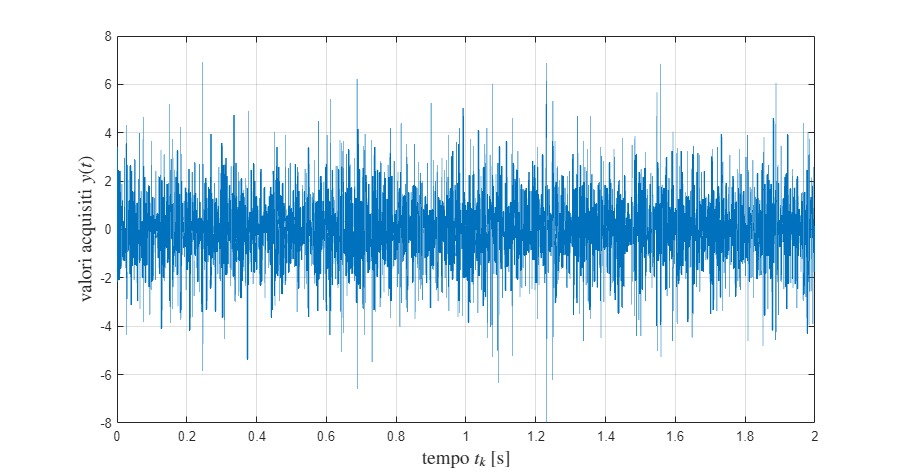


N1 = size(serie1,2); % % 20 righe x N1 colonne -- ogni realizzazione ha N1 campioni
t1 = (0:N1-1).*Ts; % istanti di tempo di campionamento

figure('Units','normalized','Position',[0.1, 0.1, 0.8, 0.75]);
plot(t1, y1, 'LineWidth', 1.5);
grid on;
xlabel('tempo $t_k$ [s]','Interpreter','latex','FontSize',14);
ylabel('valori acquisiti $y(t)$','Interpreter','latex','FontSize',14);

% inserisci il codice che risolve il problema proposto
% usa dei brevi commenti nel codice, per rendere il codice più leggibile

- per ciascuna delle $3$ serie di realizzazioni si utilizzino gli indici FPE, AIC, MDL per individuare quale sia il modello $AR$ di complessità ottima per i dati a disposizione e commentare il risultato ottenuto.

- al modello individuato al punto precedente applicare il test di Anderson, ripetendo il test facendo uso di tutte le realizzazioni della serie. Commentare il risultato ottenuto.

- valutare per ciascuna realizzazione della serie l'incertezza di stima del vettore dei parametri del modello ottimo identificato a partire dai dati della singola realizzazione  facendo uso della formula teorica $\mathrm{var}\left[\hat{\vartheta}_{N_1}\right] = \hat{\lambda}^2_{N_1}\, \left [ \,\sum_{t=1}^{N_1} \,\varphi(t)
\, \varphi(t)^{\top} \, \right ]^{-1}$

### processing the first serie

for i = 1:size(serie1,1)
    processSerie(serie1(i,:), Ts)
end

### processing the second serie

for i = 1:size(serie2,1)
    processSerie(serie2(i,:), Ts)
end

y_av = -0.0022

*** Done! Time spent analysing AR models: 0.030221 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               14      
    best AR - AIC         5               14      
    best AR - MDL         5               14      



(:,:,1) =

   1.0e-03 *

    0.4851    0.6603    0.5702    0.3830    0.1336


(:,:,2) =

    0.0007    0.0013    0.0013    0.0009    0.0004


(:,:,3) =

    0.0006    0.0013    0.0017    0.0013    0.0006


(:,:,4) =

    0.0004    0.0009    0.0013    0.0013    0.0007


(:,:,5) =

   1.0e-03 *

    0.1336    0.3824    0.5701    0.6600    0.4845



y_av = 0.0015

*** Done! Time spent analysing AR models: 0.018949 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               6       
    best AR - AIC         5               6       
    best AR - MDL         5               6       



(:,:,1) =

   1.0e-03 *

    0.4876    0.6640    0.5589    0.3827    0.1344


(:,:,2) =

    0.0007    0.0014    0.0013    0.0009    0.0004


(:,:,3) =

    0.0006    0.0013    0.0017    0.0013    0.0006


(:,:,4) =

    0.0004    0.0009    0.0013    0.0014    0.0007


(:,:,5) =

   1.0e-03 *

    0.1344    0.3826    0.5590    0.6649    0.4883



y_av = -0.0051

*** Done! Time spent analysing AR models: 0.011679 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               16      
    best AR - AIC         5               16      
    best AR - MDL         5               16      



(:,:,1) =

   1.0e-03 *

    0.4922    0.7041    0.6093    0.3892    0.1210


(:,:,2) =

    0.0007    0.0015    0.0015    0.0010    0.0004


(:,:,3) =

    0.0006    0.0015    0.0019    0.0015    0.0006


(:,:,4) =

    0.0004    0.0010    0.0015    0.0015    0.0007


(:,:,5) =

   1.0e-03 *

    0.1210    0.3888    0.6099    0.7066    0.4940



y_av = 0.0024

*** Done! Time spent analysing AR models: 0.011921 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               6       
    best AR - AIC         5               6       
    best AR - MDL         5               6       



(:,:,1) =

   1.0e-03 *

    0.4915    0.6854    0.6016    0.4058    0.1296


(:,:,2) =

    0.0007    0.0014    0.0014    0.0010    0.0004


(:,:,3) =

    0.0006    0.0014    0.0018    0.0014    0.0006


(:,:,4) =

    0.0004    0.0010    0.0014    0.0014    0.0007


(:,:,5) =

   1.0e-03 *

    0.1296    0.4043    0.5997    0.6834    0.4903



y_av = -4.2557e-04

*** Done! Time spent analysing AR models: 0.009665 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               12      
    best AR - AIC         5               12      
    best AR - MDL         5               12      



(:,:,1) =

   1.0e-03 *

    0.4872    0.6660    0.5491    0.3483    0.1128


(:,:,2) =

    0.0007    0.0014    0.0013    0.0009    0.0003


(:,:,3) =

    0.0005    0.0013    0.0017    0.0013    0.0005


(:,:,4) =

    0.0003    0.0009    0.0013    0.0014    0.0007


(:,:,5) =

   1.0e-03 *

    0.1128    0.3469    0.5485    0.6645    0.4856



y_av = -4.9685e-04

*** Done! Time spent analysing AR models: 0.011463 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               8       
    best AR - AIC         5               8       
    best AR - MDL         5               8       



(:,:,1) =

   1.0e-03 *

    0.4928    0.6732    0.5731    0.3961    0.1276


(:,:,2) =

    0.0007    0.0014    0.0014    0.0010    0.0004


(:,:,3) =

    0.0006    0.0014    0.0017    0.0014    0.0006


(:,:,4) =

    0.0004    0.0010    0.0014    0.0014    0.0007


(:,:,5) =

   1.0e-03 *

    0.1276    0.3965    0.5737    0.6727    0.4932



y_av = 4.2278e-04

*** Done! Time spent analysing AR models: 0.011782 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               0       
    best AR - AIC         5               0       
    best AR - MDL         5               0       



(:,:,1) =

   1.0e-03 *

    0.4809    0.6729    0.5720    0.3846    0.1308


(:,:,2) =

    0.0007    0.0014    0.0014    0.0010    0.0004


(:,:,3) =

    0.0006    0.0014    0.0018    0.0014    0.0006


(:,:,4) =

    0.0004    0.0010    0.0014    0.0014    0.0007


(:,:,5) =

   1.0e-03 *

    0.1308    0.3852    0.5740    0.6756    0.4824



y_av = -0.0031

*** Done! Time spent analysing AR models: 0.011393 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               8       
    best AR - AIC         5               8       
    best AR - MDL         5               8       



(:,:,1) =

   1.0e-03 *

    0.4889    0.6482    0.5651    0.3869    0.1319


(:,:,2) =

    0.0006    0.0013    0.0013    0.0009    0.0004


(:,:,3) =

    0.0006    0.0013    0.0017    0.0013    0.0006


(:,:,4) =

    0.0004    0.0009    0.0013    0.0013    0.0006


(:,:,5) =

   1.0e-03 *

    0.1319    0.3868    0.5650    0.6474    0.4879



y_av = -6.4930e-04

*** Done! Time spent analysing AR models: 0.011124 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               8       
    best AR - AIC         5               8       
    best AR - MDL         5               8       



(:,:,1) =

   1.0e-03 *

    0.4894    0.6818    0.5831    0.4049    0.1510


(:,:,2) =

    0.0007    0.0014    0.0014    0.0010    0.0004


(:,:,3) =

    0.0006    0.0014    0.0017    0.0014    0.0006


(:,:,4) =

    0.0004    0.0010    0.0014    0.0014    0.0007


(:,:,5) =

   1.0e-03 *

    0.1510    0.4039    0.5813    0.6795    0.4882



y_av = -3.2750e-04

*** Done! Time spent analysing AR models: 0.014116 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               6       
    best AR - AIC         5               6       
    best AR - MDL         5               6       



(:,:,1) =

   1.0e-03 *

    0.4910    0.6727    0.5804    0.3944    0.1322


(:,:,2) =

    0.0007    0.0014    0.0014    0.0010    0.0004


(:,:,3) =

    0.0006    0.0014    0.0017    0.0014    0.0006


(:,:,4) =

    0.0004    0.0010    0.0014    0.0014    0.0007


(:,:,5) =

   1.0e-03 *

    0.1322    0.3940    0.5809    0.6743    0.4923



y_av = -0.0017

*** Done! Time spent analysing AR models: 0.011350 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               12      
    best AR - AIC         5               12      
    best AR - MDL         5               12      



(:,:,1) =

   1.0e-03 *

    0.4907    0.6917    0.5944    0.4243    0.1545


(:,:,2) =

    0.0007    0.0014    0.0014    0.0010    0.0004


(:,:,3) =

    0.0006    0.0014    0.0018    0.0014    0.0006


(:,:,4) =

    0.0004    0.0010    0.0014    0.0014    0.0007


(:,:,5) =

   1.0e-03 *

    0.1545    0.4239    0.5933    0.6902    0.4897



y_av = 6.8924e-04

*** Done! Time spent analysing AR models: 0.011341 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               8       
    best AR - AIC         5               8       
    best AR - MDL         5               8       



(:,:,1) =

   1.0e-03 *

    0.4888    0.6787    0.5588    0.3546    0.1103


(:,:,2) =

    0.0007    0.0014    0.0014    0.0009    0.0004


(:,:,3) =

    0.0006    0.0014    0.0018    0.0014    0.0006


(:,:,4) =

    0.0004    0.0009    0.0014    0.0014    0.0007


(:,:,5) =

   1.0e-03 *

    0.1103    0.3543    0.5580    0.6771    0.4871



y_av = -0.0033

*** Done! Time spent analysing AR models: 0.011237 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               8       
    best AR - AIC         5               8       
    best AR - MDL         5               8       



(:,:,1) =

   1.0e-03 *

    0.4889    0.6700    0.5708    0.3792    0.1195


(:,:,2) =

    0.0007    0.0014    0.0014    0.0010    0.0004


(:,:,3) =

    0.0006    0.0014    0.0017    0.0014    0.0006


(:,:,4) =

    0.0004    0.0010    0.0014    0.0014    0.0007


(:,:,5) =

   1.0e-03 *

    0.1195    0.3790    0.5706    0.6693    0.4879



y_av = -0.0058

*** Done! Time spent analysing AR models: 0.012320 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               12      
    best AR - AIC         5               12      
    best AR - MDL         5               12      



(:,:,1) =

   1.0e-03 *

    0.4862    0.6968    0.5895    0.3817    0.1270


(:,:,2) =

    0.0007    0.0015    0.0014    0.0010    0.0004


(:,:,3) =

    0.0006    0.0014    0.0019    0.0014    0.0006


(:,:,4) =

    0.0004    0.0010    0.0014    0.0015    0.0007


(:,:,5) =

   1.0e-03 *

    0.1270    0.3816    0.5893    0.6967    0.4859



y_av = -0.0020

*** Done! Time spent analysing AR models: 0.012659 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               8       
    best AR - AIC         5               8       
    best AR - MDL         5               8       



(:,:,1) =

   1.0e-03 *

    0.4875    0.6557    0.5560    0.3623    0.1190


(:,:,2) =

    0.0007    0.0013    0.0013    0.0009    0.0004


(:,:,3) =

    0.0006    0.0013    0.0017    0.0013    0.0006


(:,:,4) =

    0.0004    0.0009    0.0013    0.0013    0.0007


(:,:,5) =

   1.0e-03 *

    0.1190    0.3618    0.5561    0.6559    0.4869



y_av = 0.0019

*** Done! Time spent analysing AR models: 0.011571 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               8       
    best AR - AIC         5               8       
    best AR - MDL         5               8       



(:,:,1) =

   1.0e-03 *

    0.4883    0.6650    0.5609    0.3787    0.1268


(:,:,2) =

    0.0007    0.0014    0.0013    0.0009    0.0004


(:,:,3) =

    0.0006    0.0013    0.0017    0.0013    0.0006


(:,:,4) =

    0.0004    0.0009    0.0013    0.0014    0.0007


(:,:,5) =

   1.0e-03 *

    0.1268    0.3787    0.5610    0.6649    0.4885



y_av = -0.0094

*** Done! Time spent analysing AR models: 0.011651 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               10      
    best AR - AIC         5               10      
    best AR - MDL         5               10      



(:,:,1) =

   1.0e-03 *

    0.4813    0.6688    0.5653    0.3827    0.1306


(:,:,2) =

    0.0007    0.0014    0.0014    0.0009    0.0004


(:,:,3) =

    0.0006    0.0014    0.0017    0.0014    0.0006


(:,:,4) =

    0.0004    0.0009    0.0014    0.0014    0.0007


(:,:,5) =

   1.0e-03 *

    0.1306    0.3830    0.5661    0.6698    0.4815



y_av = 4.0082e-04

*** Done! Time spent analysing AR models: 0.010961 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               0       
    best AR - AIC         5               0       
    best AR - MDL         5               0       



(:,:,1) =

   1.0e-03 *

    0.4883    0.6613    0.5618    0.3755    0.1378


(:,:,2) =

    0.0007    0.0013    0.0013    0.0009    0.0004


(:,:,3) =

    0.0006    0.0013    0.0017    0.0013    0.0006


(:,:,4) =

    0.0004    0.0009    0.0013    0.0013    0.0007


(:,:,5) =

   1.0e-03 *

    0.1378    0.3760    0.5617    0.6592    0.4871



y_av = -0.0041

*** Done! Time spent analysing AR models: 0.041166 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               10      
    best AR - AIC         5               10      
    best AR - MDL         5               10      



(:,:,1) =

   1.0e-03 *

    0.4853    0.6551    0.5570    0.3696    0.1291


(:,:,2) =

    0.0007    0.0013    0.0013    0.0009    0.0004


(:,:,3) =

    0.0006    0.0013    0.0017    0.0013    0.0006


(:,:,4) =

    0.0004    0.0009    0.0013    0.0013    0.0007


(:,:,5) =

   1.0e-03 *

    0.1291    0.3697    0.5569    0.6550    0.4854



y_av = -0.0060

*** Done! Time spent analysing AR models: 0.013278 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               16      
    best AR - AIC         5               16      
    best AR - MDL         5               16      



(:,:,1) =

   1.0e-03 *

    0.4891    0.6801    0.5852    0.3920    0.1276


(:,:,2) =

    0.0007    0.0014    0.0014    0.0010    0.0004


(:,:,3) =

    0.0006    0.0014    0.0018    0.0014    0.0006


(:,:,4) =

    0.0004    0.0010    0.0014    0.0014    0.0007


(:,:,5) =

   1.0e-03 *

    0.1276    0.3918    0.5854    0.6807    0.4896



### processing the third serie

for i = 1:size(serie3,1)
    processSerie(serie3(i,:), Ts)
end

y_av = -3.8219e-04

*** Done! Time spent analysing AR models: 0.019421 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               12      
    best AR - AIC         5               12      
    best AR - MDL         5               12      



(:,:,1) =

   1.0e-03 *

    0.2434    0.3419    0.2977    0.1991    0.0657


(:,:,2) =

   1.0e-03 *

    0.3419    0.7059    0.7065    0.4971    0.1991


(:,:,3) =

   1.0e-03 *

    0.2977    0.7065    0.9082    0.7072    0.2980


(:,:,4) =

   1.0e-03 *

    0.1991    0.4971    0.7072    0.7072    0.3425


(:,:,5) =

   1.0e-03 *

    0.0657    0.1991    0.2980    0.3425    0.2439



y_av = 8.5314e-04

*** Done! Time spent analysing AR models: 0.017907 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               0       
    best AR - AIC         5               0       
    best AR - MDL         5               0       



(:,:,1) =

   1.0e-03 *

    0.2436    0.3393    0.2921    0.1975    0.0675


(:,:,2) =

   1.0e-03 *

    0.3393    0.6974    0.6913    0.4862    0.1975


(:,:,3) =

   1.0e-03 *

    0.2921    0.6913    0.8876    0.6914    0.2922


(:,:,4) =

   1.0e-03 *

    0.1975    0.4862    0.6914    0.6975    0.3394


(:,:,5) =

   1.0e-03 *

    0.0675    0.1975    0.2922    0.3394    0.2437



y_av = -0.0011

*** Done! Time spent analysing AR models: 0.019723 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               22      
    best AR - AIC         5               22      
    best AR - MDL         5               22      



(:,:,1) =

   1.0e-03 *

    0.2460    0.3404    0.2910    0.1967    0.0677


(:,:,2) =

   1.0e-03 *

    0.3404    0.6986    0.6890    0.4830    0.1966


(:,:,3) =

   1.0e-03 *

    0.2910    0.6890    0.8855    0.6890    0.2910


(:,:,4) =

   1.0e-03 *

    0.1967    0.4830    0.6890    0.6985    0.3405


(:,:,5) =

   1.0e-03 *

    0.0677    0.1966    0.2910    0.3405    0.2460



y_av = -9.4213e-04

*** Done! Time spent analysing AR models: 0.019043 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               26      
    best AR - AIC         5               26      
    best AR - MDL         5               26      



(:,:,1) =

   1.0e-03 *

    0.2441    0.3380    0.2922    0.1998    0.0665


(:,:,2) =

   1.0e-03 *

    0.3380    0.6939    0.6880    0.4891    0.1998


(:,:,3) =

   1.0e-03 *

    0.2922    0.6880    0.8801    0.6880    0.2920


(:,:,4) =

   1.0e-03 *

    0.1998    0.4891    0.6880    0.6938    0.3379


(:,:,5) =

   1.0e-03 *

    0.0665    0.1998    0.2920    0.3379    0.2440



y_av = -0.0013

*** Done! Time spent analysing AR models: 0.018968 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               24      
    best AR - AIC         5               24      
    best AR - MDL         5               24      



(:,:,1) =

   1.0e-03 *

    0.2445    0.3318    0.2830    0.1904    0.0617


(:,:,2) =

   1.0e-03 *

    0.3318    0.6793    0.6680    0.4701    0.1905


(:,:,3) =

   1.0e-03 *

    0.2830    0.6680    0.8588    0.6681    0.2832


(:,:,4) =

   1.0e-03 *

    0.1904    0.4701    0.6681    0.6795    0.3320


(:,:,5) =

   1.0e-03 *

    0.0617    0.1905    0.2832    0.3320    0.2446



y_av = 5.3928e-04

*** Done! Time spent analysing AR models: 0.018591 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               22      
    best AR - AIC         5               22      
    best AR - MDL         5               22      



(:,:,1) =

   1.0e-03 *

    0.2431    0.3331    0.2862    0.1868    0.0586


(:,:,2) =

   1.0e-03 *

    0.3331    0.6853    0.6800    0.4729    0.1867


(:,:,3) =

   1.0e-03 *

    0.2862    0.6800    0.8785    0.6799    0.2860


(:,:,4) =

   1.0e-03 *

    0.1868    0.4729    0.6799    0.6853    0.3332


(:,:,5) =

   1.0e-03 *

    0.0586    0.1867    0.2860    0.3332    0.2433



y_av = -0.0033

*** Done! Time spent analysing AR models: 0.018989 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               24      
    best AR - AIC         5               24      
    best AR - MDL         5               24      



(:,:,1) =

   1.0e-03 *

    0.2439    0.3372    0.2873    0.1892    0.0626


(:,:,2) =

   1.0e-03 *

    0.3372    0.6940    0.6859    0.4753    0.1893


(:,:,3) =

   1.0e-03 *

    0.2873    0.6859    0.8858    0.6861    0.2875


(:,:,4) =

   1.0e-03 *

    0.1892    0.4753    0.6861    0.6948    0.3377


(:,:,5) =

   1.0e-03 *

    0.0626    0.1893    0.2875    0.3377    0.2444



y_av = -0.0029

*** Done! Time spent analysing AR models: 0.017909 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               14      
    best AR - AIC         5               14      
    best AR - MDL         5               14      



(:,:,1) =

   1.0e-03 *

    0.2440    0.3394    0.2944    0.1969    0.0686


(:,:,2) =

   1.0e-03 *

    0.3394    0.6971    0.6937    0.4855    0.1968


(:,:,3) =

   1.0e-03 *

    0.2944    0.6937    0.8933    0.6937    0.2943


(:,:,4) =

   1.0e-03 *

    0.1969    0.4855    0.6937    0.6973    0.3396


(:,:,5) =

   1.0e-03 *

    0.0686    0.1968    0.2943    0.3396    0.2442



y_av = -6.0115e-04

*** Done! Time spent analysing AR models: 0.020362 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               24      
    best AR - AIC         5               24      
    best AR - MDL         5               24      



(:,:,1) =

   1.0e-03 *

    0.2421    0.3354    0.2832    0.1932    0.0683


(:,:,2) =

   1.0e-03 *

    0.3354    0.6875    0.6732    0.4709    0.1933


(:,:,3) =

   1.0e-03 *

    0.2832    0.6732    0.8643    0.6728    0.2830


(:,:,4) =

   1.0e-03 *

    0.1932    0.4709    0.6728    0.6867    0.3348


(:,:,5) =

   1.0e-03 *

    0.0683    0.1933    0.2830    0.3348    0.2416



y_av = -0.0026

*** Done! Time spent analysing AR models: 0.030451 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               20      
    best AR - AIC         5               20      
    best AR - MDL         5               20      



(:,:,1) =

   1.0e-03 *

    0.2432    0.3321    0.2809    0.1868    0.0637


(:,:,2) =

   1.0e-03 *

    0.3321    0.6799    0.6667    0.4623    0.1867


(:,:,3) =

   1.0e-03 *

    0.2809    0.6667    0.8609    0.6667    0.2808


(:,:,4) =

   1.0e-03 *

    0.1868    0.4623    0.6667    0.6800    0.3320


(:,:,5) =

   1.0e-03 *

    0.0637    0.1867    0.2808    0.3320    0.2430



y_av = -0.0011

*** Done! Time spent analysing AR models: 0.018186 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               20      
    best AR - AIC         5               20      
    best AR - MDL         5               20      



(:,:,1) =

   1.0e-03 *

    0.2467    0.3412    0.2957    0.1982    0.0680


(:,:,2) =

   1.0e-03 *

    0.3412    0.6999    0.6958    0.4885    0.1982


(:,:,3) =

   1.0e-03 *

    0.2957    0.6958    0.8956    0.6961    0.2958


(:,:,4) =

   1.0e-03 *

    0.1982    0.4885    0.6961    0.7003    0.3414


(:,:,5) =

   1.0e-03 *

    0.0680    0.1982    0.2958    0.3414    0.2467



y_av = 0.0028

*** Done! Time spent analysing AR models: 0.018017 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               16      
    best AR - AIC         5               16      
    best AR - MDL         5               16      



(:,:,1) =

   1.0e-03 *

    0.2439    0.3335    0.2873    0.1925    0.0655


(:,:,2) =

   1.0e-03 *

    0.3335    0.6824    0.6747    0.4733    0.1925


(:,:,3) =

   1.0e-03 *

    0.2873    0.6747    0.8689    0.6747    0.2873


(:,:,4) =

   1.0e-03 *

    0.1925    0.4733    0.6747    0.6824    0.3336


(:,:,5) =

   1.0e-03 *

    0.0655    0.1925    0.2873    0.3336    0.2441



y_av = 0.0019

*** Done! Time spent analysing AR models: 0.019154 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               14      
    best AR - AIC         5               14      
    best AR - MDL         5               14      



(:,:,1) =

   1.0e-03 *

    0.2455    0.3390    0.2826    0.1885    0.0657


(:,:,2) =

   1.0e-03 *

    0.3390    0.6961    0.6789    0.4673    0.1885


(:,:,3) =

   1.0e-03 *

    0.2826    0.6789    0.8767    0.6789    0.2826


(:,:,4) =

   1.0e-03 *

    0.1885    0.4673    0.6789    0.6962    0.3391


(:,:,5) =

   1.0e-03 *

    0.0657    0.1885    0.2826    0.3391    0.2455



y_av = -0.0040

*** Done! Time spent analysing AR models: 0.018767 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               0       
    best AR - AIC         5               0       
    best AR - MDL         5               0       



(:,:,1) =

   1.0e-03 *

    0.2432    0.3387    0.2848    0.1883    0.0614


(:,:,2) =

   1.0e-03 *

    0.3387    0.6992    0.6877    0.4751    0.1883


(:,:,3) =

   1.0e-03 *

    0.2848    0.6877    0.8869    0.6876    0.2848


(:,:,4) =

   1.0e-03 *

    0.1883    0.4751    0.6876    0.6992    0.3387


(:,:,5) =

   1.0e-03 *

    0.0614    0.1883    0.2848    0.3387    0.2432



y_av = 0.0028

*** Done! Time spent analysing AR models: 0.018586 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               20      
    best AR - AIC         5               20      
    best AR - MDL         5               20      



(:,:,1) =

   1.0e-03 *

    0.2435    0.3329    0.2852    0.1949    0.0650


(:,:,2) =

   1.0e-03 *

    0.3329    0.6813    0.6707    0.4755    0.1948


(:,:,3) =

   1.0e-03 *

    0.2852    0.6707    0.8596    0.6712    0.2854


(:,:,4) =

   1.0e-03 *

    0.1949    0.4755    0.6712    0.6822    0.3335


(:,:,5) =

   1.0e-03 *

    0.0650    0.1948    0.2854    0.3335    0.2441



y_av = 2.9172e-04

*** Done! Time spent analysing AR models: 0.018718 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               24      
    best AR - AIC         5               24      
    best AR - MDL         5               24      



(:,:,1) =

   1.0e-03 *

    0.2453    0.3385    0.2918    0.1968    0.0663


(:,:,2) =

   1.0e-03 *

    0.3385    0.6944    0.6878    0.4844    0.1968


(:,:,3) =

   1.0e-03 *

    0.2918    0.6878    0.8833    0.6876    0.2917


(:,:,4) =

   1.0e-03 *

    0.1968    0.4844    0.6876    0.6940    0.3383


(:,:,5) =

   1.0e-03 *

    0.0663    0.1968    0.2917    0.3383    0.2452



y_av = -6.1641e-04

*** Done! Time spent analysing AR models: 0.018049 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               22      
    best AR - AIC         5               22      
    best AR - MDL         5               22      



(:,:,1) =

   1.0e-03 *

    0.2455    0.3416    0.2923    0.1979    0.0694


(:,:,2) =

   1.0e-03 *

    0.3416    0.7008    0.6919    0.4848    0.1977


(:,:,3) =

   1.0e-03 *

    0.2923    0.6919    0.8891    0.6920    0.2921


(:,:,4) =

   1.0e-03 *

    0.1979    0.4848    0.6920    0.7008    0.3414


(:,:,5) =

   1.0e-03 *

    0.0694    0.1977    0.2921    0.3414    0.2454



y_av = -0.0013

*** Done! Time spent analysing AR models: 0.018246 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               26      
    best AR - AIC         5               26      
    best AR - MDL         5               26      



(:,:,1) =

   1.0e-03 *

    0.2416    0.3266    0.2692    0.1789    0.0597


(:,:,2) =

   1.0e-03 *

    0.3266    0.6682    0.6462    0.4445    0.1789


(:,:,3) =

   1.0e-03 *

    0.2692    0.6462    0.8356    0.6462    0.2692


(:,:,4) =

   1.0e-03 *

    0.1789    0.4445    0.6462    0.6681    0.3265


(:,:,5) =

   1.0e-03 *

    0.0597    0.1789    0.2692    0.3265    0.2415



y_av = -2.0751e-05

*** Done! Time spent analysing AR models: 0.017952 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               18      
    best AR - AIC         5               18      
    best AR - MDL         5               18      



(:,:,1) =

   1.0e-03 *

    0.2438    0.3328    0.2854    0.1919    0.0686


(:,:,2) =

   1.0e-03 *

    0.3328    0.6787    0.6684    0.4670    0.1919


(:,:,3) =

   1.0e-03 *

    0.2854    0.6684    0.8618    0.6683    0.2854


(:,:,4) =

   1.0e-03 *

    0.1919    0.4670    0.6683    0.6785    0.3327


(:,:,5) =

   1.0e-03 *

    0.0686    0.1919    0.2854    0.3327    0.2437



y_av = -0.0024

*** Done! Time spent analysing AR models: 0.018493 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               18      
    best AR - AIC         5               18      
    best AR - MDL         5               18      



(:,:,1) =

   1.0e-03 *

    0.2457    0.3401    0.2904    0.1978    0.0662


(:,:,2) =

   1.0e-03 *

    0.3401    0.6986    0.6887    0.4859    0.1978


(:,:,3) =

   1.0e-03 *

    0.2904    0.6887    0.8825    0.6885    0.2904


(:,:,4) =

   1.0e-03 *

    0.1978    0.4859    0.6885    0.6978    0.3396


(:,:,5) =

   1.0e-03 *

    0.0662    0.1978    0.2904    0.3396    0.2453



## Results

*individuare quale sia il modello *$AR$* di complessità ottima per i dati a disposizione e commentare il risultato ottenuto.*

There's no optimal AR model with order $\leq 5$ that can solve the problem. For all the examinated cases (an "unhandled" string is printed in case we are getting that the best model is not the fifth, and this case has never been evaluated during this livescript's execution) we get that the best model is the 5th order (which is the maximum we can compute) and that in most of the cases this model doesn't satisfy the Anderson test.

Sometimes we get a model able to pass Anderson's test, but the general trend is that we are not able to pass it. What's interesting to note, is that we aren't able to pass the Anderson's test for jsut a couple of points, but in many cases we are not passing it because of $\gt 10$ points. This can confirm us that it's not a problem concerning how we collected the measures, but it's a problem with our model set (AR(n) $n \leq 5$) not being powerful enough to estimate the problem. In fact all the different realizations, also having different number of data points are confirming us that (AR(n) $n \leq 5$) is not enough.

*per quanto riguarda l'incertezza della stima, commentare i risultati ottenuti, al variare della numerosità dei dati utilizzati (cioè confrontando i risultati ottenuti usando una serie di dati con quelli ottenuti con le altre serie di dati).*

Having a look at the estimate uncertainty, we can state that it's not improving as the number of examined data increases (we can notice that there's a factor being multiplied to the variance matrix which is always in the order of $10^{-3}$). This is a strange behavior as one would expect the variance to improve as the number of data increases. This could be due to the fact of the data being too noisy (low SNR). This last statement is compliant with the result got at the previous point (we can't figure out an AR(n) $n \leq 5$ able to estimate the problem with a sufficient degree of quality).

The reason we are not able to find a model able to approximate the problem with a sufficiently good degree of accuracy, might be that:

1.the data is too noisy

for i = 1:20
    v = var(serie1(i,:));
    m = mean(serie1(1,:));

y_av = -0.0026

*** Done! Time spent analysing AR models: 0.028687 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               28      
    best AR - AIC         5               28      
    best AR - MDL         5               28      



(:,:,1) =

   1.0e-03 *

    0.1612    0.2195    0.1841    0.1200    0.0380


(:,:,2) =

   1.0e-03 *

    0.2195    0.4512    0.4419    0.3041    0.1200


(:,:,3) =

   1.0e-03 *

    0.1841    0.4419    0.5720    0.4419    0.1840


(:,:,4) =

   1.0e-03 *

    0.1200    0.3041    0.4419    0.4512    0.2195


(:,:,5) =

   1.0e-03 *

    0.0380    0.1200    0.1840    0.2195    0.1611



y_av = -0.0025

*** Done! Time spent analysing AR models: 0.027505 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               42      
    best AR - AIC         5               42      
    best AR - MDL         5               42      



(:,:,1) =

   1.0e-03 *

    0.1621    0.2230    0.1897    0.1272    0.0440


(:,:,2) =

   1.0e-03 *

    0.2230    0.4570    0.4495    0.3132    0.1272


(:,:,3) =

   1.0e-03 *

    0.1897    0.4495    0.5792    0.4495    0.1898


(:,:,4) =

   1.0e-03 *

    0.1272    0.3132    0.4495    0.4570    0.2231


(:,:,5) =

   1.0e-03 *

    0.0440    0.1272    0.1898    0.2231    0.1622



y_av = 0.0028

*** Done! Time spent analysing AR models: 0.030516 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               16      
    best AR - AIC         5               16      
    best AR - MDL         5               16      



(:,:,1) =

   1.0e-03 *

    0.1633    0.2244    0.1905    0.1251    0.0412


(:,:,2) =

   1.0e-03 *

    0.2244    0.4614    0.4547    0.3144    0.1251


(:,:,3) =

   1.0e-03 *

    0.1905    0.4547    0.5876    0.4546    0.1904


(:,:,4) =

   1.0e-03 *

    0.1251    0.3144    0.4546    0.4611    0.2242


(:,:,5) =

   1.0e-03 *

    0.0412    0.1251    0.1904    0.2242    0.1630



y_av = -0.0021

*** Done! Time spent analysing AR models: 0.026293 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               36      
    best AR - AIC         5               36      
    best AR - MDL         5               36      



(:,:,1) =

   1.0e-03 *

    0.1625    0.2252    0.1940    0.1330    0.0461


(:,:,2) =

   1.0e-03 *

    0.2252    0.4616    0.4564    0.3232    0.1329


(:,:,3) =

   1.0e-03 *

    0.1940    0.4564    0.5844    0.4564    0.1940


(:,:,4) =

   1.0e-03 *

    0.1330    0.3232    0.4564    0.4616    0.2253


(:,:,5) =

   1.0e-03 *

    0.0461    0.1329    0.1940    0.2253    0.1625



y_av = -0.0040

*** Done! Time spent analysing AR models: 0.028066 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               38      
    best AR - AIC         5               38      
    best AR - MDL         5               38      



(:,:,1) =

   1.0e-03 *

    0.1633    0.2275    0.1946    0.1320    0.0458


(:,:,2) =

   1.0e-03 *

    0.2275    0.4673    0.4616    0.3240    0.1320


(:,:,3) =

   1.0e-03 *

    0.1946    0.4616    0.5927    0.4617    0.1946


(:,:,4) =

   1.0e-03 *

    0.1320    0.3240    0.4617    0.4674    0.2275


(:,:,5) =

   1.0e-03 *

    0.0458    0.1320    0.1946    0.2275    0.1633



y_av = 4.6452e-05

*** Done! Time spent analysing AR models: 0.027261 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               24      
    best AR - AIC         5               24      
    best AR - MDL         5               24      



(:,:,1) =

   1.0e-03 *

    0.1627    0.2236    0.1918    0.1276    0.0412


(:,:,2) =

   1.0e-03 *

    0.2236    0.4595    0.4549    0.3186    0.1276


(:,:,3) =

   1.0e-03 *

    0.1918    0.4549    0.5858    0.4551    0.1919


(:,:,4) =

   1.0e-03 *

    0.1276    0.3186    0.4551    0.4598    0.2238


(:,:,5) =

   1.0e-03 *

    0.0412    0.1276    0.1919    0.2238    0.1628



y_av = -0.0015

*** Done! Time spent analysing AR models: 0.030061 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               24      
    best AR - AIC         5               24      
    best AR - MDL         5               24      



(:,:,1) =

   1.0e-03 *

    0.1621    0.2262    0.1911    0.1280    0.0422


(:,:,2) =

   1.0e-03 *

    0.2262    0.4668    0.4596    0.3200    0.1280


(:,:,3) =

   1.0e-03 *

    0.1911    0.4596    0.5911    0.4596    0.1911


(:,:,4) =

   1.0e-03 *

    0.1280    0.3200    0.4596    0.4667    0.2262


(:,:,5) =

   1.0e-03 *

    0.0422    0.1280    0.1911    0.2262    0.1621



y_av = 1.8720e-05

*** Done! Time spent analysing AR models: 0.027136 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               22      
    best AR - AIC         5               22      
    best AR - MDL         5               22      



(:,:,1) =

   1.0e-03 *

    0.1619    0.2226    0.1920    0.1267    0.0407


(:,:,2) =

   1.0e-03 *

    0.2226    0.4577    0.4547    0.3179    0.1267


(:,:,3) =

   1.0e-03 *

    0.1920    0.4547    0.5863    0.4547    0.1920


(:,:,4) =

   1.0e-03 *

    0.1267    0.3179    0.4547    0.4577    0.2226


(:,:,5) =

   1.0e-03 *

    0.0407    0.1267    0.1920    0.2226    0.1619



y_av = 0.0016

*** Done! Time spent analysing AR models: 0.031308 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               28      
    best AR - AIC         5               28      
    best AR - MDL         5               28      



(:,:,1) =

   1.0e-03 *

    0.1623    0.2195    0.1852    0.1221    0.0408


(:,:,2) =

   1.0e-03 *

    0.2195    0.4489    0.4393    0.3038    0.1221


(:,:,3) =

   1.0e-03 *

    0.1852    0.4393    0.5683    0.4392    0.1852


(:,:,4) =

   1.0e-03 *

    0.1221    0.3038    0.4392    0.4487    0.2194


(:,:,5) =

   1.0e-03 *

    0.0408    0.1221    0.1852    0.2194    0.1622



y_av = 0.0017

*** Done! Time spent analysing AR models: 0.027193 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               22      
    best AR - AIC         5               22      
    best AR - MDL         5               22      



(:,:,1) =

   1.0e-03 *

    0.1622    0.2243    0.1919    0.1263    0.0412


(:,:,2) =

   1.0e-03 *

    0.2243    0.4617    0.4575    0.3178    0.1263


(:,:,3) =

   1.0e-03 *

    0.1919    0.4575    0.5904    0.4574    0.1919


(:,:,4) =

   1.0e-03 *

    0.1263    0.3178    0.4574    0.4615    0.2241


(:,:,5) =

   1.0e-03 *

    0.0412    0.1263    0.1919    0.2241    0.1622



y_av = -1.4643e-04

*** Done! Time spent analysing AR models: 0.027621 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               34      
    best AR - AIC         5               34      
    best AR - MDL         5               34      



(:,:,1) =

   1.0e-03 *

    0.1627    0.2237    0.1921    0.1283    0.0426


(:,:,2) =

   1.0e-03 *

    0.2237    0.4590    0.4541    0.3181    0.1281


(:,:,3) =

   1.0e-03 *

    0.1921    0.4541    0.5845    0.4540    0.1919


(:,:,4) =

   1.0e-03 *

    0.1283    0.3181    0.4540    0.4589    0.2235


(:,:,5) =

   1.0e-03 *

    0.0426    0.1281    0.1919    0.2235    0.1624



y_av = 2.8677e-04

*** Done! Time spent analysing AR models: 0.028068 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               0       
    best AR - AIC         5               0       
    best AR - MDL         5               0       



(:,:,1) =

   1.0e-03 *

    0.1617    0.2256    0.1957    0.1313    0.0441


(:,:,2) =

   1.0e-03 *

    0.2256    0.4645    0.4629    0.3255    0.1313


(:,:,3) =

   1.0e-03 *

    0.1957    0.4629    0.5949    0.4630    0.1957


(:,:,4) =

   1.0e-03 *

    0.1313    0.3255    0.4630    0.4646    0.2257


(:,:,5) =

   1.0e-03 *

    0.0441    0.1313    0.1957    0.2257    0.1617



y_av = 5.4601e-04

*** Done! Time spent analysing AR models: 0.028273 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               24      
    best AR - AIC         5               24      
    best AR - MDL         5               24      



(:,:,1) =

   1.0e-03 *

    0.1632    0.2252    0.1953    0.1325    0.0443


(:,:,2) =

   1.0e-03 *

    0.2252    0.4619    0.4588    0.3253    0.1325


(:,:,3) =

   1.0e-03 *

    0.1953    0.4588    0.5880    0.4587    0.1952


(:,:,4) =

   1.0e-03 *

    0.1325    0.3253    0.4587    0.4618    0.2250


(:,:,5) =

   1.0e-03 *

    0.0443    0.1325    0.1952    0.2250    0.1630



y_av = -0.0038

*** Done! Time spent analysing AR models: 0.027399 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               40      
    best AR - AIC         5               40      
    best AR - MDL         5               40      



(:,:,1) =

   1.0e-03 *

    0.1606    0.2229    0.1890    0.1262    0.0420


(:,:,2) =

   1.0e-03 *

    0.2229    0.4589    0.4522    0.3147    0.1262


(:,:,3) =

   1.0e-03 *

    0.1890    0.4522    0.5823    0.4522    0.1891


(:,:,4) =

   1.0e-03 *

    0.1262    0.3147    0.4522    0.4590    0.2229


(:,:,5) =

   1.0e-03 *

    0.0420    0.1262    0.1891    0.2229    0.1606



y_av = -0.0011

*** Done! Time spent analysing AR models: 0.029779 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               36      
    best AR - AIC         5               36      
    best AR - MDL         5               36      



(:,:,1) =

   1.0e-03 *

    0.1611    0.2207    0.1862    0.1222    0.0410


(:,:,2) =

   1.0e-03 *

    0.2207    0.4529    0.4446    0.3061    0.1222


(:,:,3) =

   1.0e-03 *

    0.1862    0.4446    0.5752    0.4444    0.1862


(:,:,4) =

   1.0e-03 *

    0.1222    0.3061    0.4444    0.4526    0.2205


(:,:,5) =

   1.0e-03 *

    0.0410    0.1222    0.1862    0.2205    0.1610



y_av = 0.0023

*** Done! Time spent analysing AR models: 0.027078 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               20      
    best AR - AIC         5               20      
    best AR - MDL         5               20      



(:,:,1) =

   1.0e-03 *

    0.1621    0.2255    0.1900    0.1262    0.0430


(:,:,2) =

   1.0e-03 *

    0.2255    0.4644    0.4563    0.3150    0.1261


(:,:,3) =

   1.0e-03 *

    0.1900    0.4563    0.5889    0.4564    0.1900


(:,:,4) =

   1.0e-03 *

    0.1262    0.3150    0.4564    0.4646    0.2256


(:,:,5) =

   1.0e-03 *

    0.0430    0.1261    0.1900    0.2256    0.1622



y_av = -0.0030

*** Done! Time spent analysing AR models: 0.027002 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               26      
    best AR - AIC         5               26      
    best AR - MDL         5               26      



(:,:,1) =

   1.0e-03 *

    0.1625    0.2241    0.1923    0.1293    0.0442


(:,:,2) =

   1.0e-03 *

    0.2241    0.4597    0.4543    0.3184    0.1293


(:,:,3) =

   1.0e-03 *

    0.1923    0.4543    0.5847    0.4545    0.1924


(:,:,4) =

   1.0e-03 *

    0.1293    0.3184    0.4545    0.4600    0.2243


(:,:,5) =

   1.0e-03 *

    0.0442    0.1293    0.1924    0.2243    0.1626



y_av = 9.2903e-04

*** Done! Time spent analysing AR models: 0.028802 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               28      
    best AR - AIC         5               28      
    best AR - MDL         5               28      



(:,:,1) =

   1.0e-03 *

    0.1611    0.2227    0.1879    0.1275    0.0431


(:,:,2) =

   1.0e-03 *

    0.2227    0.4575    0.4483    0.3139    0.1276


(:,:,3) =

   1.0e-03 *

    0.1879    0.4483    0.5754    0.4481    0.1878


(:,:,4) =

   1.0e-03 *

    0.1275    0.3139    0.4481    0.4572    0.2226


(:,:,5) =

   1.0e-03 *

    0.0431    0.1276    0.1878    0.2226    0.1611



y_av = -0.0024

*** Done! Time spent analysing AR models: 0.029472 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               26      
    best AR - AIC         5               26      
    best AR - MDL         5               26      



(:,:,1) =

   1.0e-03 *

    0.1625    0.2253    0.1937    0.1286    0.0439


(:,:,2) =

   1.0e-03 *

    0.2253    0.4629    0.4590    0.3196    0.1286


(:,:,3) =

   1.0e-03 *

    0.1937    0.4590    0.5919    0.4590    0.1937


(:,:,4) =

   1.0e-03 *

    0.1286    0.3196    0.4590    0.4629    0.2253


(:,:,5) =

   1.0e-03 *

    0.0439    0.1286    0.1937    0.2253    0.1625



y_av = -9.9644e-04

*** Done! Time spent analysing AR models: 0.027436 [s] ***



ans = 3×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________

    best AR - FPE         5               22      
    best AR - AIC         5               22      
    best AR - MDL         5               22      



(:,:,1) =

   1.0e-03 *

    0.1617    0.2217    0.1908    0.1291    0.0434


(:,:,2) =

   1.0e-03 *

    0.2217    0.4540    0.4486    0.3166    0.1291


(:,:,3) =

   1.0e-03 *

    0.1908    0.4486    0.5761    0.4486    0.1908


(:,:,4) =

   1.0e-03 *

    0.1291    0.3166    0.4486    0.4539    0.2217


(:,:,5) =

   1.0e-03 *

    0.0434    0.1291    0.1908    0.2217    0.1617



    disp("1var  "+v)
    disp("1mean "+m)
end
for i = 1:20
    v = var(serie2(i,:));
    m = mean(serie2(1,:));
    disp("2var  "+v)
    disp("2mean "+m)
end
for i = 1:20
    v = var(serie3(i,:));
    m = mean(serie3(1,:));
    disp("3var  "+v)
    disp("3mean "+m)
end

1var  3.6302


1mean -0.0021582


1var  3.6178


1mean -0.0021582


1var  4.1058


1mean -0.0021582


1var  3.6699


1mean -0.0021582


1var  3.9103


1mean -0.0021582


1var  3.6406


1mean -0.0021582


1var  3.7409


1mean -0.0021582


1var  3.2697


1mean -0.0021582


1var  3.918


1mean -0.0021582


1var  3.7504


1mean -0.0021582


1var  3.9555


1mean -0.0021582


1var  3.7402


1mean -0.0021582


1var  3.8904


1mean -0.0021582


1var  4.0136


1mean -0.0021582


1var  3.4764


1mean -0.0021582


1var  3.6842


1mean -0.0021582


1var  3.8113


1mean -0.0021582


1var  3.4953


1mean -0.0021582


1var  3.5781


1mean -0.0021582


1var  3.8112


1mean -0.0021582


having a look at the provided data, we can notice that the variance is quite high compared to the mean value for all the cases, so this first hypothesis might actually be true.

2. The model we are trying to estimate is not an AR

3. We have to increase the order of AR we are trying to estimate

One or more of the last hypothesis can be true at the same time.

function y = processSerie(Y_S1, Ts)
    Ndata = numel(Y_S1);
    timeVector = Ts .* (0: Ndata-1);
    y_av = mean(Y_S1)
    Y_S1 = Y_S1 - y_av;


2var  3.8766


2mean -0.00038219


2var  3.9652


2mean -0.00038219


2var  3.6725


2mean -0.00038219


2var  3.8712


2mean -0.00038219


2var  3.6321


2mean -0.00038219


2var  3.6175


2mean -0.00038219


2var  3.7986


2mean -0.00038219


2var  3.7461


2mean -0.00038219


2var  3.943


2mean -0.00038219


2var  3.681


2mean -0.00038219


2var  3.7676


2mean -0.00038219


2var  3.609


2mean -0.00038219


2var  3.6779


2mean -0.00038219


2var  3.9751


2mean -0.00038219


2var  3.7259


2mean -0.00038219


2var  3.6649


2mean -0.00038219


2var  3.9011


2mean -0.00038219


2var  3.8134


2mean -0.00038219


2var  3.5054


2mean -0.00038219


2var  3.8752


2mean -0.00038219


    nA_MAX = 5; % let us analyse the AR(n) models untill n = nA_MAX
    nA_SET = (1:nA_MAX);

    ARmodels = cell(nA_MAX, 1);
    ARresiduals = cell(nA_MAX, 1);
    AR_LossVal = zeros(nA_MAX, 1);

3var  3.7414


3mean -0.0026416


3var  3.8228


3mean -0.0026416


3var  3.7237


3mean -0.0026416


3var  3.8013


3mean -0.0026416


3var  3.9201


3mean -0.0026416


3var  3.7357


3mean -0.0026416


3var  4.0815


3mean -0.0026416


3var  3.6544


3mean -0.0026416


3var  3.5437


3mean -0.0026416


3var  3.8266


3mean -0.0026416


3var  3.7288


3mean -0.0026416


3var  3.8619


3mean -0.0026416


3var  3.6054


3mean -0.0026416


3var  3.9424


3mean -0.0026416


3var  3.7019


3mean -0.0026416


3var  3.9221


3mean -0.0026416


3var  3.8082


3mean -0.0026416


3var  3.9042


3mean -0.0026416


3var  3.7814


3mean -0.0026416


3var  3.6091


3mean -0.0026416


    
    AR_AndersonWT = zeros(3,1);   
    
    FPEresult = zeros(nA_MAX,1);
    AICresult = zeros(nA_MAX,1);
    MDLresult = zeros(nA_MAX,1);
    var_theta_N = zeros(nA_MAX, nA_MAX, nA_MAX);
    
    tic
    for nA = nA_SET % for each model AR(n) under test
                  
        Y_AR = Y_S1;
        % if it is not a row, just transpose it!
        if ~isrow(Y_AR)
            Y_AR = Y_AR';
        end
                
        matPHI = zeros(Ndata-nA, nA); 
        % preallocation of the PHI regressors matrix
    
        % --- filling the matPHI matrix ---
        for k = nA+1:Ndata
            kk = k-nA;
            matPHI(kk,:) = fliplr(Y_AR(k-nA:k-1));
            % matPHI(t,:) = [y(t-1), y(t-2), ... y(t-nA)]
        end % for k

                        
        Y_N = Y_AR(nA+1:end)';   
        % a column vector, without the initial nA values
    
        % -- identifying the model ---
        hat_theta_N = pinv(matPHI)* Y_N; % alternatively --> matPHI \ Y_N;
        % the minimum of the cost function
        pred_residuals = Y_N - matPHI*hat_theta_N;


valutare per ciascuna realizzazione della serie l'incertezza di stima del vettore dei parametri del modello ottimo identificato a partire dai dati della singola realizzazione  facendo uso della formula teorica $\mathrm{var}\left[\hat{\vartheta}_{N_1}\right] = \hat{\lambda}^2_{N_1}\, \left [ \,\sum_{t=1}^{N_1} \,\varphi(t)
\, \varphi(t)^{\top} \, \right ]^{-1}$

        S_N1 = matPHI'*matPHI;
        hat_lambda2_N1 = mean((pred_residuals).^2);
        var_theta_N1 = hat_lambda2_N1 .* inv(S_N1);
        for i = 1:size(var_theta_N1, 1)
            for j = 1:size(var_theta_N1, 2)
                var_theta_N(nA, i,j) = var_theta_N1(i,j);
            end
        end

        J_loss = mean((pred_residuals).^2) ;
    
        ARmodels{nA} = hat_theta_N; % storing the model
        AR_LossVal(nA) = J_loss; % storing the loss value
        ARresiduals{nA} = pred_residuals;
    
        % now let us evaluate the FPE, AIC and MDL indices 
        % for each model using currNdata data
        N = Ndata;
        n = nA;
        FPEresult(n) = ((N+n)/(N-n)) * J_loss;
        AICresult(n) = 2*(n/N) + log(J_loss);
        MDLresult(n) = log(N)*(n/N) + log(J_loss);
    
    end % for nA -- for each model AR(n) under test END
    
    elapsed_t = toc;
    
    fprintf(1, '*** Done! Time spent analysing AR models: %f [s] ***\n\r', elapsed_t);

    [aic_min,aic_id] = min(AICresult);
    [fpe_min,fpe_id] = min(FPEresult);
    [mdl_min,mdl_id] = min(MDLresult);
    
    
    aic_best_ar = ARmodels{aic_id};aic_best_ar_Name = 'best AR - AIC';
    fpe_best_ar = ARmodels{fpe_id};fpe_best_ar_Name = 'best AR - FPE';
    mdl_best_ar = ARmodels{mdl_id};mdl_best_ar_Name = 'best AR - MDL';
    
% TODO    
    FPE_N = 1; AIC_N = 2; MDL_N = 3;
    best_scores_order = [fpe_id; aic_id; mdl_id ];

    AR_AndersonWT(FPE_N) = AndersonWhitenessTest(ARresiduals{fpe_id}, 0.05, false);
    AR_AndersonWT(AIC_N) = AndersonWhitenessTest(ARresiduals{aic_id}, 0.05, false);
    AR_AndersonWT(MDL_N) = AndersonWhitenessTest(ARresiduals{mdl_id}, 0.05, false);

    final_scores = [best_scores_order , AR_AndersonWT ];
    RowLabels = cell(3,1);
    RowLabels{FPE_N} = fpe_best_ar_Name;
    RowLabels{AIC_N} = aic_best_ar_Name;
    RowLabels{MDL_N} = mdl_best_ar_Name;
    
    VarNames = {'AR(n) order', 'Whiteness Test'};
    
    array2table(final_scores, "RowNames",RowLabels, "VariableNames", VarNames)

    if aic_id == fpe_id && aic_id == mdl_id && fpe_id == mdl_id
        disp(var_theta_N(aic_id,:,:));
    else
        disp("UNHANDLED!!!")
    end

end